clear; close; clc;
Ltotal = 1137.15 % lbf

Ltotal = 1.1372e+03

Vroot = Ltotal % lbf

Vroot = 1.1372e+03

c1 = 8.42

c1 = 8.4200

Mroot = 76867.9 % lbf*in

Mroot = 7.6868e+04


stepSize = 1 % inches; make this small for more acurrate

stepSize = 1


steps = (160-15)/stepSize +1

steps = 146


% X = linspace(15,140,steps) %defined later
% X = [15:stepSize:140] use linspace insea to definetly include endpoint



% l = lift, V = shear, M = moment, t = theta, v = displacement.
Data = zeros(6,steps) %row 1 = x, 2 = l, 3 = V, 4 = M, 5 = theta, 6 = v

Data =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

Data(1,:) = linspace(15,160,steps);

liftSlope =  (0-c1) / (160-140);

% set up initial conditions
Data(2,1) = c1; % from equation (*)
Data(3,1) = Vroot; % from equilibruim
Data(4,1) = Mroot; % from equilibruim
Data(5,1) = 0; % no initial angular deflection
Data(6,1) = 0; % no initial lateral deflection

E = 1; I = 1 %TODO: implement E and I of wing with actual values

I = 1

disp("TODO: implement E and I of wing with actual values")

TODO: implement E and I of wing with actual values


EOld = 1; IOld = 1 %TODO: implement EOld and IOld of wing with actual values

IOld = 1

disp("TODO: implement EOld and IOld of wing with actual values")

TODO: implement EOld and IOld of wing with actual values


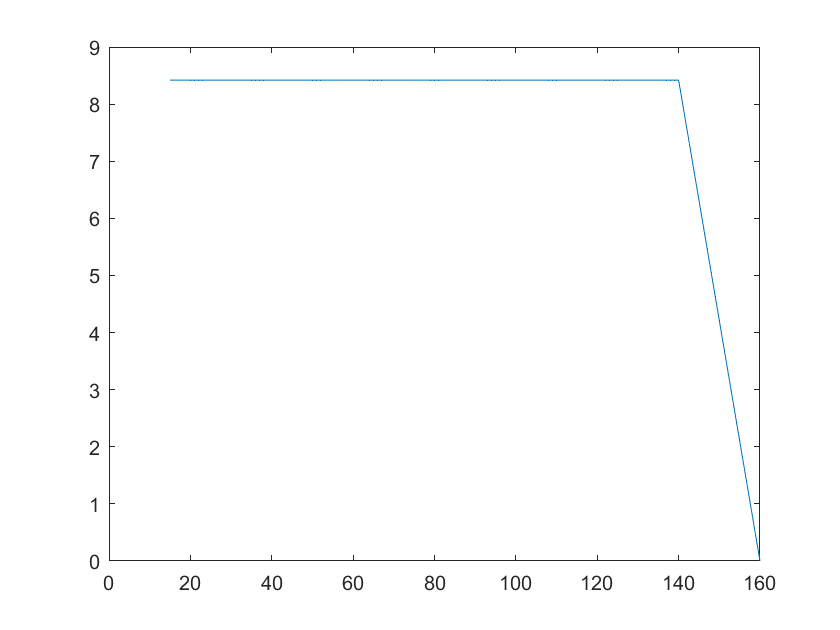

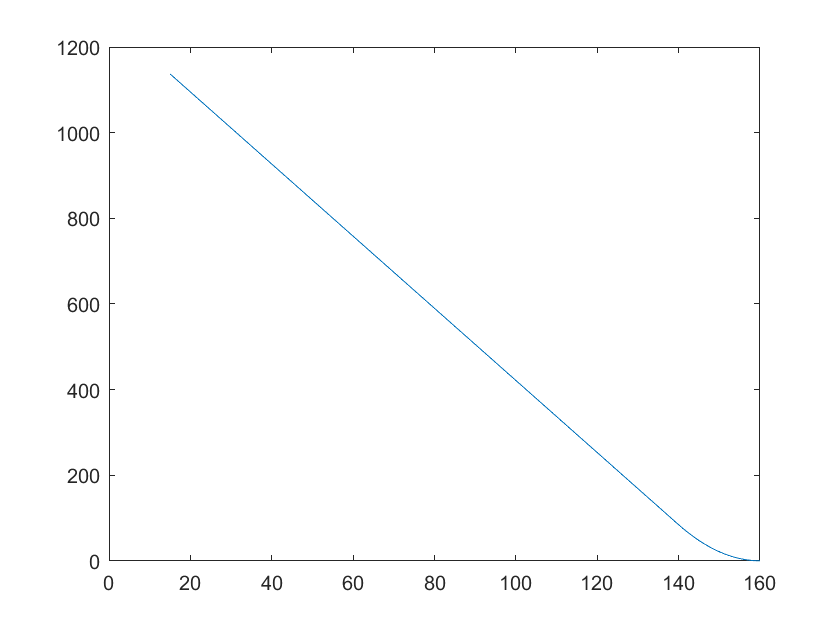

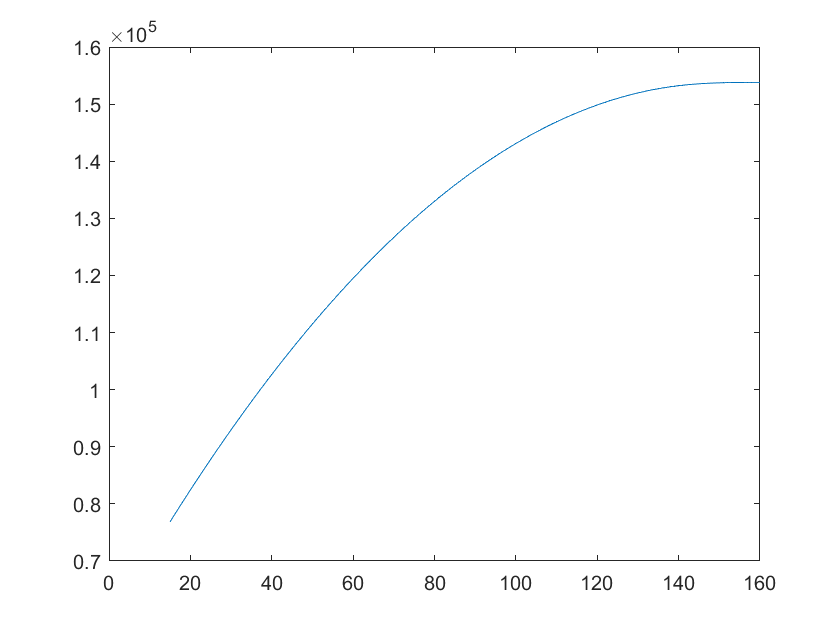

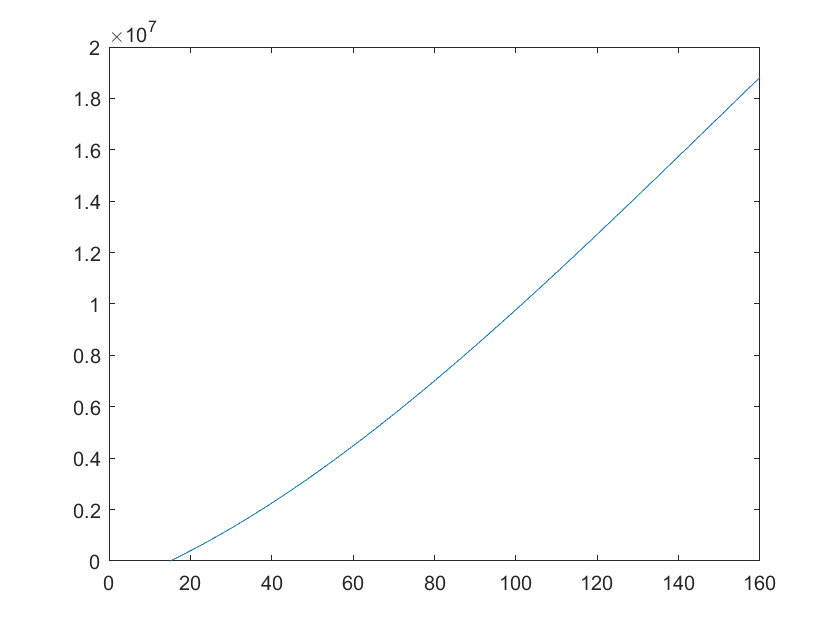

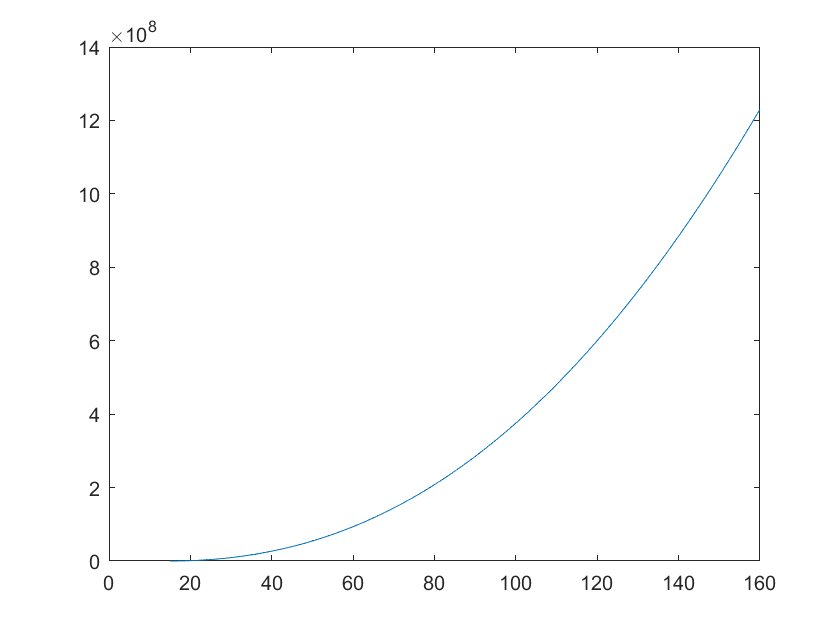


% numeric integration of discretized diff eq's
for i = [2:size(Data,2)] %OPTIMIZE: remember previous values rather than accessing array each time
    %position
    x = Data(1,i);
    
    % lift
    if x <= 140 % is position within uniform lift region?
        l = c1;
    else % position is in linear decreasing lift region
        l = c1 + liftSlope * (x-140); %point slope formula defining lift of sloped region
    end
    Data(2,i) = l;
    
    % shear
    lOld = Data(2,i-1);
    VOld = Data(3,i-1);
    V = VOld - (1/2) * (lOld + l) * stepSize;
    Data(3,i) = V;
    
    % moment
    MOld = Data(4,i-1);
    M = MOld + (1/2) * (VOld + V) * stepSize;
    Data(4,i) = M;
    
    % angular displacement
    %TODO: implement
    tOld = Data(5,i-1);
    t = tOld + (1/2) * (MOld/(EOld*IOld) + M/(E*I)) * stepSize;
    Data(5,i) = t;
    
    % lateral displacement
    vOld = Data(6,i-1);
    v = vOld + (1/2) * (tOld + t) * stepSize;
    Data(6,i) = v;
end


%TODO: turn each of these discrete diff eq integrators into a function then
%just call the mone after another

for var = [2:6]
    figure;
    plot(Data(1,:),Data(var,:)');
end


disp(Data)

   1.0e+09 *

  Columns 1 through 11

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008
         0    0.0000    0.0002    0.0004    0.0006    0.0010    0.0014    0.0019    0.0026    0.0032    0.0040

  Columns 12 through 22

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.00